# Simple Multithreaded Implementations

This Live Script helps you view the performance of simple parallel implementations of matrix-matrix multiplication.

% Close all existing figures. (This is important for the ".m" version of this file.)
close all

% import color scheme
my_plot_colors;

### Set number of threads

Some of the plots require knowledge about the number of threads that were used.  Set that here (default is 4).

omp_num_threads = 4;

### View raw timing data

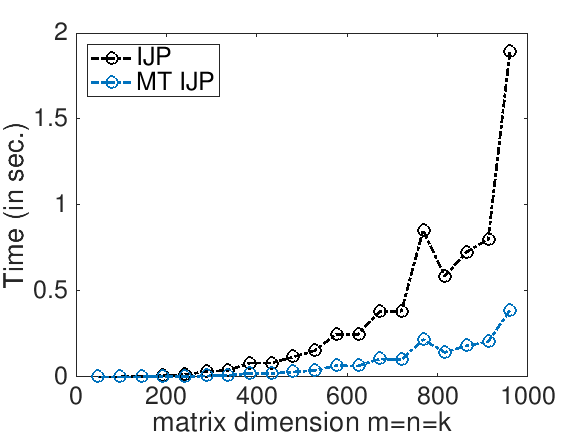


% Create figure
figure1 = figure( 'Name', 'Time' );

% Create axes, labels, legends
axes1 = axes( 'Parent', figure1 );
hold( axes1, 'on' );
ylabel( 'Time (in sec.)', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box( axes1, 'on');
set( axes1, 'FontName', 'Helvetica Neue', 'FontSize', 18);
    
% Import the data for IJP ordering
output_IJP;

% Plot time data for IJP                
plot( data(:,1), data(:,4), 'MarkerSize', 8, 'LineWidth', 2, ...
      'DisplayName', 'IJP', 'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 1,: ) );          

% save IJP data for later use
data_IJP = data;

% Import the data for MT_IJP 
output_MT_IJP;
    
% Plot time data for MT_IJP                
plot( data(:,1), data(:,4), 'MarkerSize', 8, 'LineWidth', 2, ...
      'DisplayName', 'MT IJP', 'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );          

% save MT_IJP data for later use
data_MT_IJP = data;

% Optionally, plot data for JPI loop
if ( 0 ) 
    % Import the data for JPI ordering
    output_JPI;

    % Plot time data for JPI                
    plot( data(:,1), data(:,4), 'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'JPI', 'Marker', 'x', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );          

    % save JPI dataj for later use
    data_JPI = data;

    % Import the data for MT_JPI 
    output_MT_JPI;

    % Plot time data for MT_JPI for later use           
    plot( data(:,1), data(:,4), 'MarkerSize', 8, 'LineWidth', 2, ...
         'DisplayName', 'MT JPI', 'Marker', 'x', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );          

    % save MT_JPI data
    data_MT_JPI = data;
end

% Optionally, plot reference implementations
if ( 0 )
    plot( data_IJP(:,1), data_IJP(:,2), 'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'Ref', 'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );          
    
    plot( data_MT_IJP(:,1), data_MT_IJP(:,2), 'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'MT Ref', 'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 6,: ) );          
     
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                  % extract the current ranges of the graph
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

legend1 = legend( axes1, 'show' );
set( legend1, 'Location', 'northwest', 'FontSize', 18) ;

% Uncomment if you want to create a png for the graph
print( 'Plot_MT_Timing.png', '-dpng' );

### View speedup

Speedup is computed by dividing the execution time when using a single core (thread) by the execution time when using multiple threads.

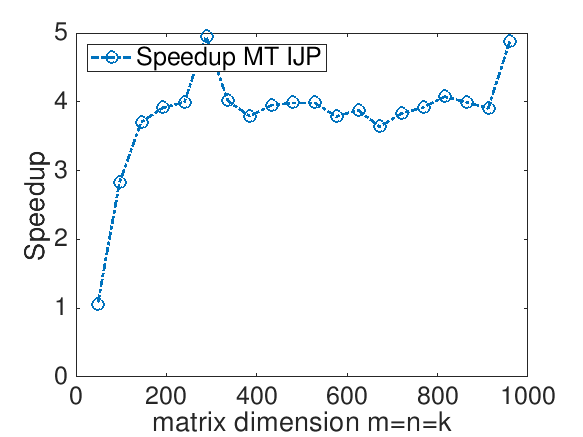

% Create figure
figure2 = figure('Name','Speedup');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes2 = axes('Parent',figure2);
hold(axes2,'on');
ylabel( 'Speedup', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes2,'on');
set( axes2, 'FontName', 'Helvetica Neue', 'FontSize', 18);         

plot( data_IJP(:,1), data_IJP(:,4) ./ data_MT_IJP( :,4 ), 'DisplayName', 'Speedup MT IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );
  
% Optionally, plot results for JPI loop
if ( 0 ) 
    plot( data_JPI(:,1), data_JPI(:,4) ./ data_MT_JPI( :,4 ), 'DisplayName', 'Speedup MT JPI', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );
end

% Optionally, plot the results for the reference implementation
if ( 0 )
plot( data_IJP(:,1), data_IJP(:,2) ./ data_MT_IJP( :,2 ), 'DisplayName', 'Speedup MT Ref', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', '+', 'LineStyle', '-.', 'Color', plot_colors( 6,: ) );
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

legend2 = legend( axes2, 'show' );
set( legend2, 'Location', 'northwest', 'FontSize', 18) ;

% Uncomment if you want to create a png for the graph
print( 'Plot_MT_Speedup.png', '-dpng' );

### View aggregate GFLOPS attained

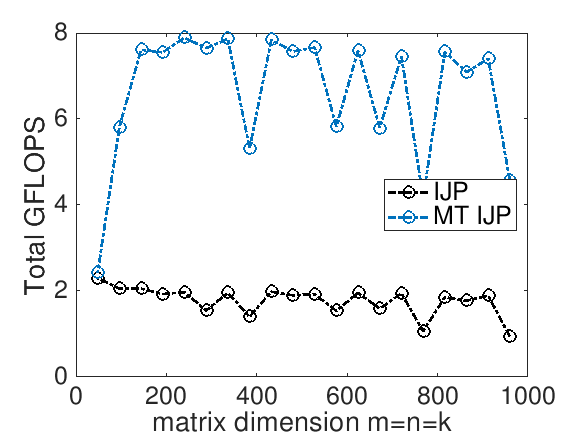

% Create figure
figure3 = figure('Name','Aggregate GFLOPS');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes3 = axes('Parent',figure3);
hold(axes3,'on');
ylabel( 'Total GFLOPS', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes3,'on');
set( axes3, 'FontName', 'Helvetica Neue', 'FontSize', 18);         

plot( data_IJP(:,1), data_IJP(:,5) , 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 1,: ) );

plot( data_MT_IJP(:,1), data_MT_IJP(:,5), 'DisplayName', 'MT IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );
  
% Optionally, plot results for JPI loop
if ( 0 ) 
    plot( data_JPI(:,1), data_JPI(:,5) , 'DisplayName', 'JPI', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );

    plot( data_MT_JPI(:,1), data_MT_JPI(:,5) , 'DisplayName', 'MT JPI', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );
end

% Optionally, plot results for the reference implementation
if ( 0 )   
    plot( data_IJP(:,1), data_IJP(:,3) , 'DisplayName', 'Ref', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );

    plot( data_MT_IJP(:,1), data_MT_IJP(:,3) , 'DisplayName', 'MT Ref', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 6,: ) );
end
  
% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

legend3 = legend( axes3, 'show' );
set( legend3, 'Location', 'east', 'FontSize', 18) ;

% Uncomment if you want to create a png for the graph
print( 'Plot_MT_GFLOPS.png', '-dpng' );

### View GFLOPS attained per thread

Finally, we view the GFLOPS that are attained, per thread.

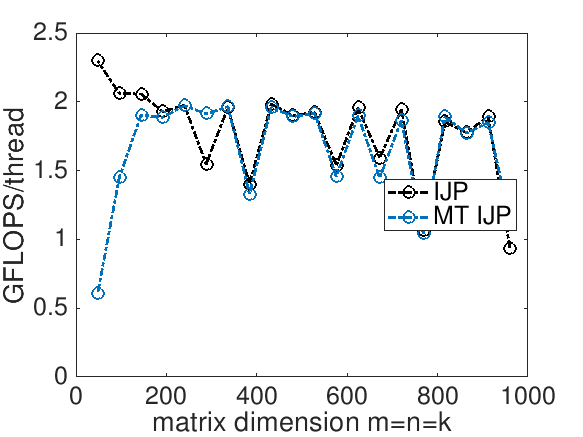

% Create figure
figure4 = figure('Name','GFLOPS/thread');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes4 = axes('Parent',figure4);
hold(axes4,'on');
ylabel( 'GFLOPS/thread', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes4,'on');
set( axes4, 'FontName', 'Helvetica Neue', 'FontSize', 18);         

plot( data_IJP(:,1), data_IJP(:,5) , 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 1,: ) );

plot( data_MT_IJP(:,1), data_MT_IJP(:,5)/omp_num_threads , 'DisplayName', 'MT IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );
  
% Optionally, plot results for JPI loop
if ( 0 ) 
    plot( data_JPI(:,1), data_JPI(:,5) , 'DisplayName', 'JPI', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );

    plot( data_MT_JPI(:,1), data_MT_JPI(:,5)/omp_num_threads , 'DisplayName', 'MT JPI', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );
end

% Optionally, plot results for the reference implementation
if ( 0 )   
    plot( data_IJP(:,1), data_IJP(:,3) , 'DisplayName', 'Ref', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );

    plot( data_MT_IJP(:,1), data_MT_IJP(:,3)/omp_num_threads , 'DisplayName', 'MT Ref', 'MarkerSize', 8, 'LineWidth', 2, ...
          'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 6,: ) );
end
  
% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

legend4 = legend( axes4, 'show' );
set( legend4, 'Location', 'east', 'FontSize', 18) ;

% Uncomment if you want to create a png for the graph
print( 'Plot_MT_GFLOPS_per_thread.png', '-dpng' );